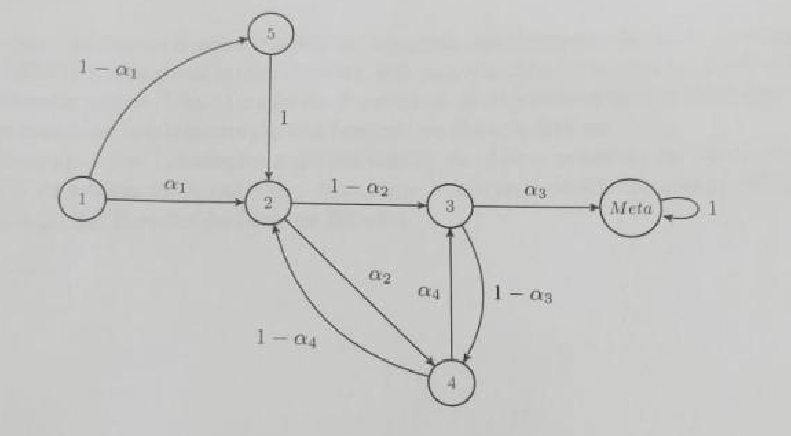

**1 - a) **Fazer a matriz de transição

a = [0.2, 0.3, 0.45, 0.1];

%    1    2    3    4    5   Meta
T = [0    0    0    0    0   0; % <-- 1
     0.2  0    0    0.9  1   0; % <-- 2
     0    0.7  0    0.1  0   0; % <-- 3
     0    0.3  0.55 0    0   0; % <-- 4
     0.8  0    0    0    0   0; % <-- 5
     0    0    0.45 0    0   1] % <-- Meta

T =          0         0         0         0         0         0
    0.2000         0         0    0.9000    1.0000         0
         0    0.7000         0    0.1000         0         0
         0    0.3000    0.5500         0         0         0
    0.8000         0         0         0         0         0
         0         0    0.4500         0         0    1.0000


**1 - b) **Probabilidade de chegar á casa meta no menor caminho possivel

x_0 = [1; 0; 0; 0; 0; 0];
x_k = zeros(length(x_0), 1);
k = 1;
while x_k(6, 1) == 0
    x_k = T^k * x_0;
    k = k + 1;
end

disp("Probabilidade de chegar á casa meta no menor caminho possivel: " + x_k(6, 1))

Probabilidade de chegar á casa meta no menor caminho possivel: 0.063


**1 - c) **Determinar o numero médio de casas percorridas desde o inicio até ao fim.

%      1    2    3    4    5   Meta
aux = [0    0    0    0    0   0; % <-- 1
       0.2  0    0    0.9  1   0; % <-- 2
       0    0.7  0    0.1  0   0; % <-- 3
       0    0.3  0.55 0    0   0; % <-- 4
       0.8  0    0    0    0   0; % <-- 5
       0    0    0.45 0    0   1] % <-- Meta

aux =          0         0         0         0         0         0
    0.2000         0         0    0.9000    1.0000         0
         0    0.7000         0    0.1000         0         0
         0    0.3000    0.5500         0         0         0
    0.8000         0         0         0         0         0
         0         0    0.4500         0         0    1.0000



Q = aux(1:5, 1:5)

Q =          0         0         0         0         0
    0.2000         0         0    0.9000    1.0000
         0    0.7000         0    0.1000         0
         0    0.3000    0.5500         0         0
    0.8000         0         0         0         0



% F = (i - Q)^(-1)
F = inv((eye(length(Q)) - Q))

F =     1.0000         0         0         0         0
    2.8767    2.8767    1.5068    2.7397    2.8767
    2.2222    2.2222    2.2222    2.2222    2.2222
    2.0852    2.0852    1.6743    3.0441    2.0852
    0.8000         0         0         0    1.0000


ans =     1.0000
   12.8767
   11.1111
   10.9741
    1.8000


media_casas_percorridas = sum(F)

media_casas_percorridas =     8.9842    7.1842    5.4033    8.0061    8.1842


media_casas_percorridas = media_casas_percorridas(1)

media_casas_percorridas = 8.9842